# Notebook 02: Preprocessing and Feature Extraction

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 02**. Before running this notebook, you should have run Notebook 01 to get an understanding of the data you will be working with.

## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

## Preprocessing

### Step 1: Load the dataset

clearvars
load('/Users/rebeccamoore/Desktop/PhD/Neuro Robotics/ResearchProject2/datasets/training_dataset.mat')

### Step 2: Visualize the raw data

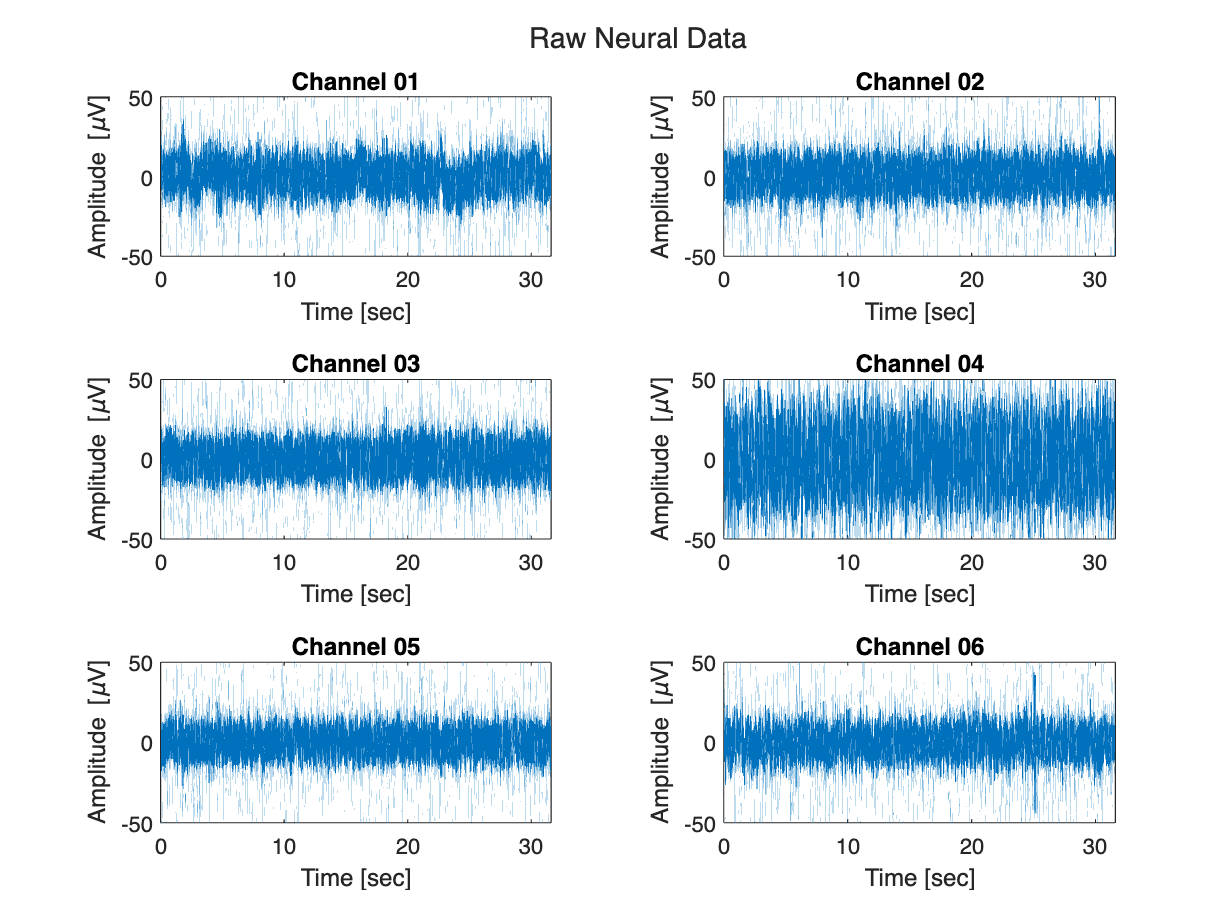

fig_1 = plot_raw_data(training_data);

### Step 3: Filter the data

#### A. Provide information for designing the filter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 500; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut-off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed.

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = filter(b, a, training_data.raw_neural_data, ch_init_conds);

#### Step 4: Visualize the filtered data

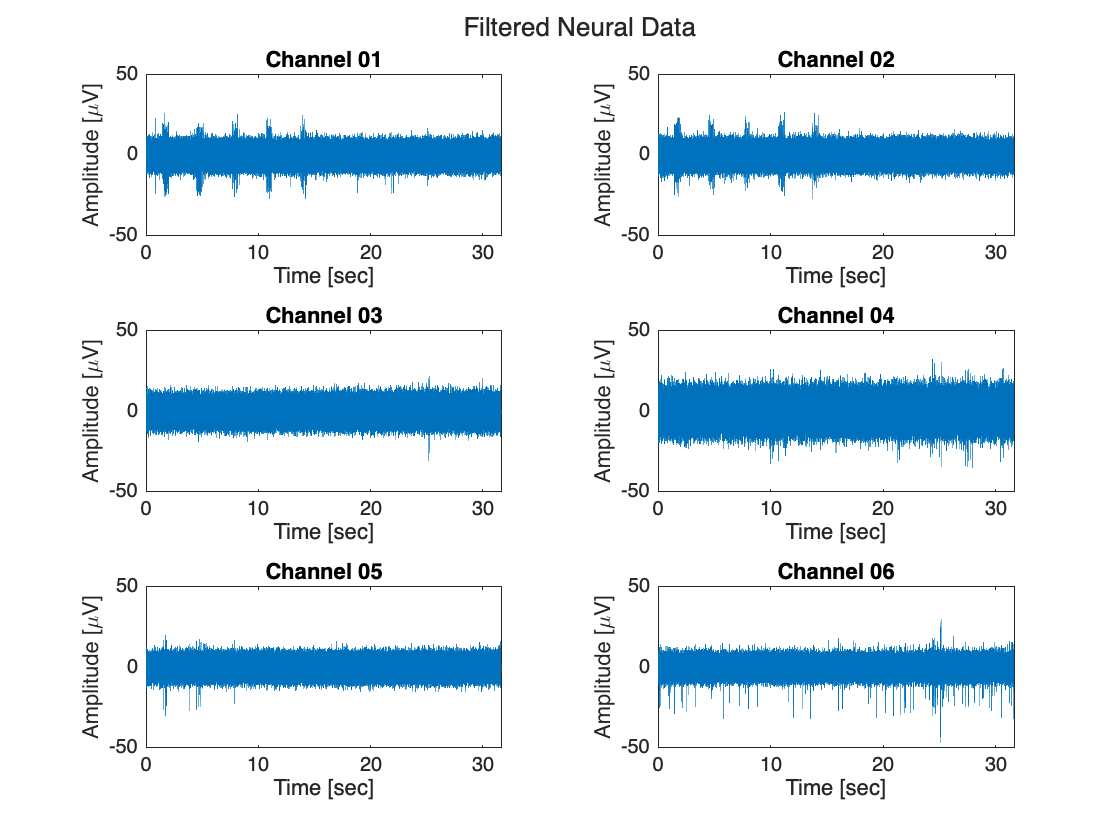

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) in all channels

Your goal for this step is to provide the locations of spike occurrences in the `filt_neural_data` matrix.

You will start with the array `spike_locations`, which has the same shape as `filt_neural_data` and whose entries have been initialized to zero.

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Then, modify the code below to replace `0`s with `1`s whenever you find a spike. We do this to leverage MATLAB's [logical indexing](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/) functionality down the line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
STD = std(filt_neural_data);
threshold = 4.25 * STD;
% Loop through each channel and detect spikes
for channel = 1:6
    channel_data = filt_neural_data(:, channel);
    
    % Detect spikes based on the threshold
    spikes(:, channel) = channel_data > threshold(channel);
    
    % Find the middle spike when consecutive spikes occur
    diff_spike = diff(spikes(:, channel));
    start_spikes = find(diff_spike == 1) + 1;  % Start of consecutive spikes
    end_spikes = find(diff_spike == -1);      % End of consecutive spikes
    
    % Remove repeating spikes and keep the middle spike
    for i = 1:length(start_spikes)
        middle_spike = round((start_spikes(i) + end_spikes(i)) / 2);
        spikes(start_spikes(i):end_spikes(i), channel) = 0;
        spikes(middle_spike, channel) = 1;
    end
end
spike_locations = spikes; % This code generates random spike locations. Replace with a spike detection algorithm

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% Diff function for spike detection 
% calculate something based on spike location, don't just feed those right in
spike_locations

spike_locations = 948199×6 logical array
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0
   0   0   0   0   0   0


### Step 2: Visualize the spike locations as spike trains in a raster plot

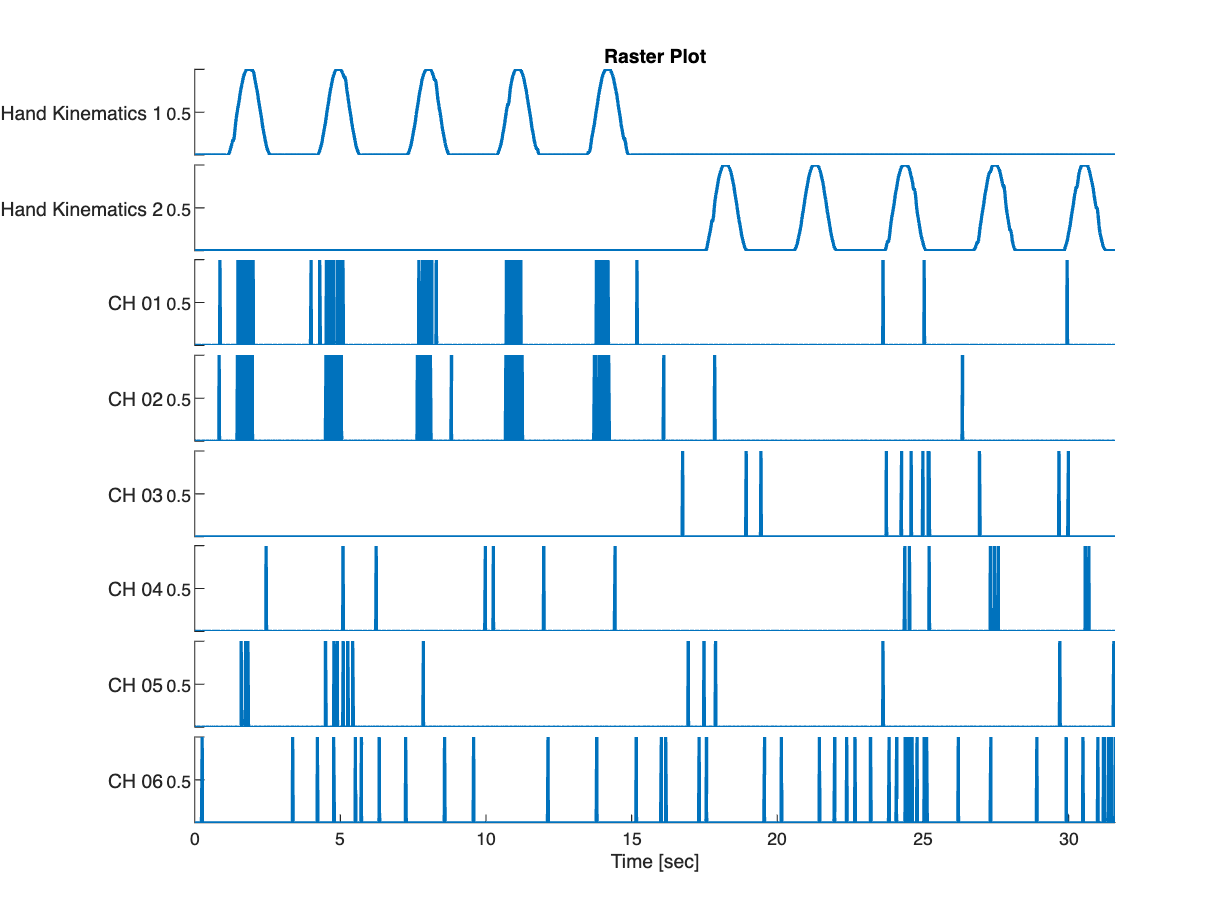

fig_3 = plot_spike_trains(spike_locations, training_data);

### Step 3: Plot the action potential waveforms using the spike locations

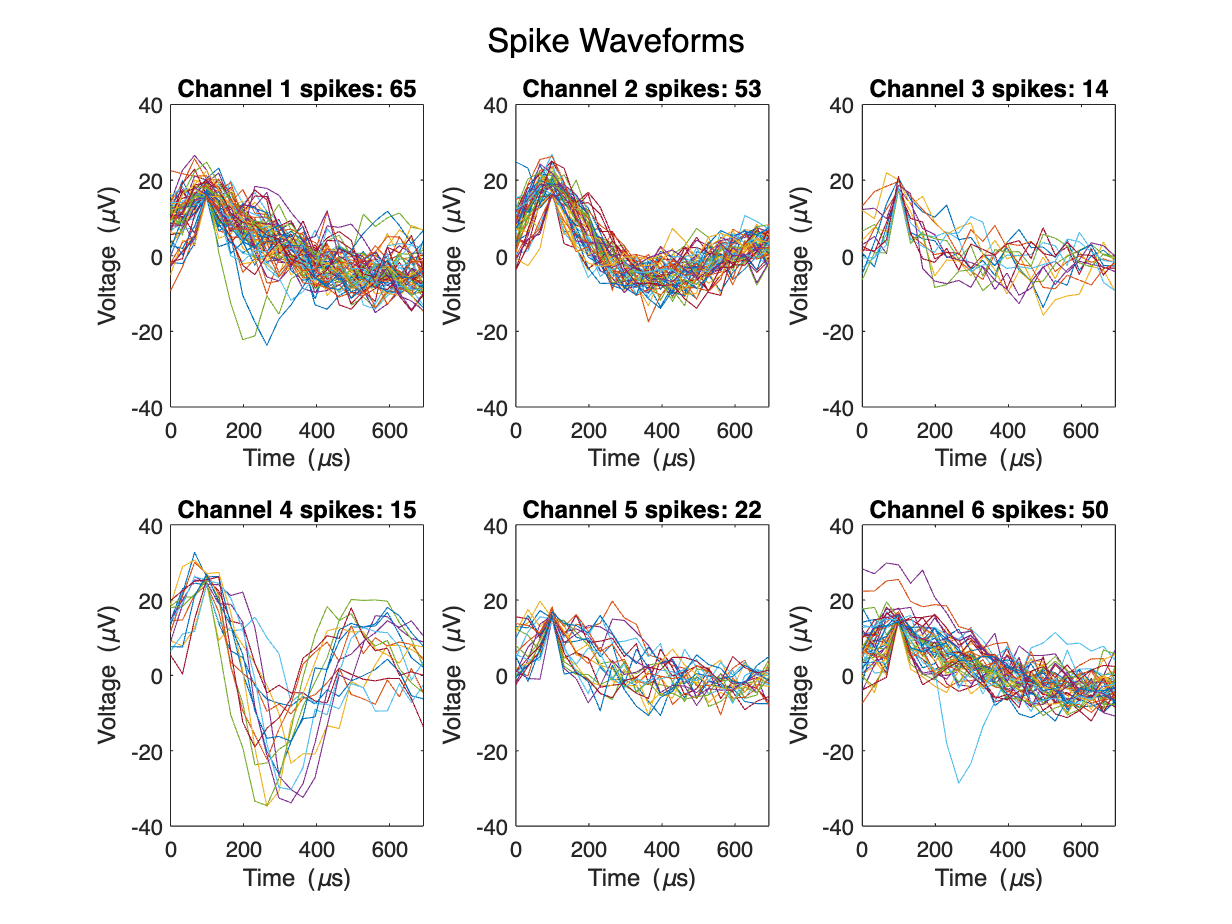

spike_waveforms = get_action_potentials(spike_locations, filt_neural_data, 'Spike Waveforms');

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms associated with each spike. 

`spike_waveforms` is a [MATLAB cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×65 cell}
    {1×53 cell}
    {1×14 cell}
    {1×15 cell}
    {1×22 cell}
    {1×50 cell}


Each one of those rows is also a cell array containing a variable number of waveforms based on the information in `spike_locations`. In order to access the waveforms, you need to specify the channel you want, and then the waveform you are interested in. The waveform itself is a vector containing `22` samples of neural data (`0.1 ms` before and `0.6 ms `after the spike detection).

chan_idx = 1; % random channel
spike_waveforms{chan_idx}

ans = 1×65 cell array
    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1

waveform_idx = 7; % random waveform
waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data = 22×1 single column vector
   13.5719
   15.1874
   16.1983
   16.4571
    8.4612
    3.3515
    7.3422
    2.4087
    5.4377
   -1.7247


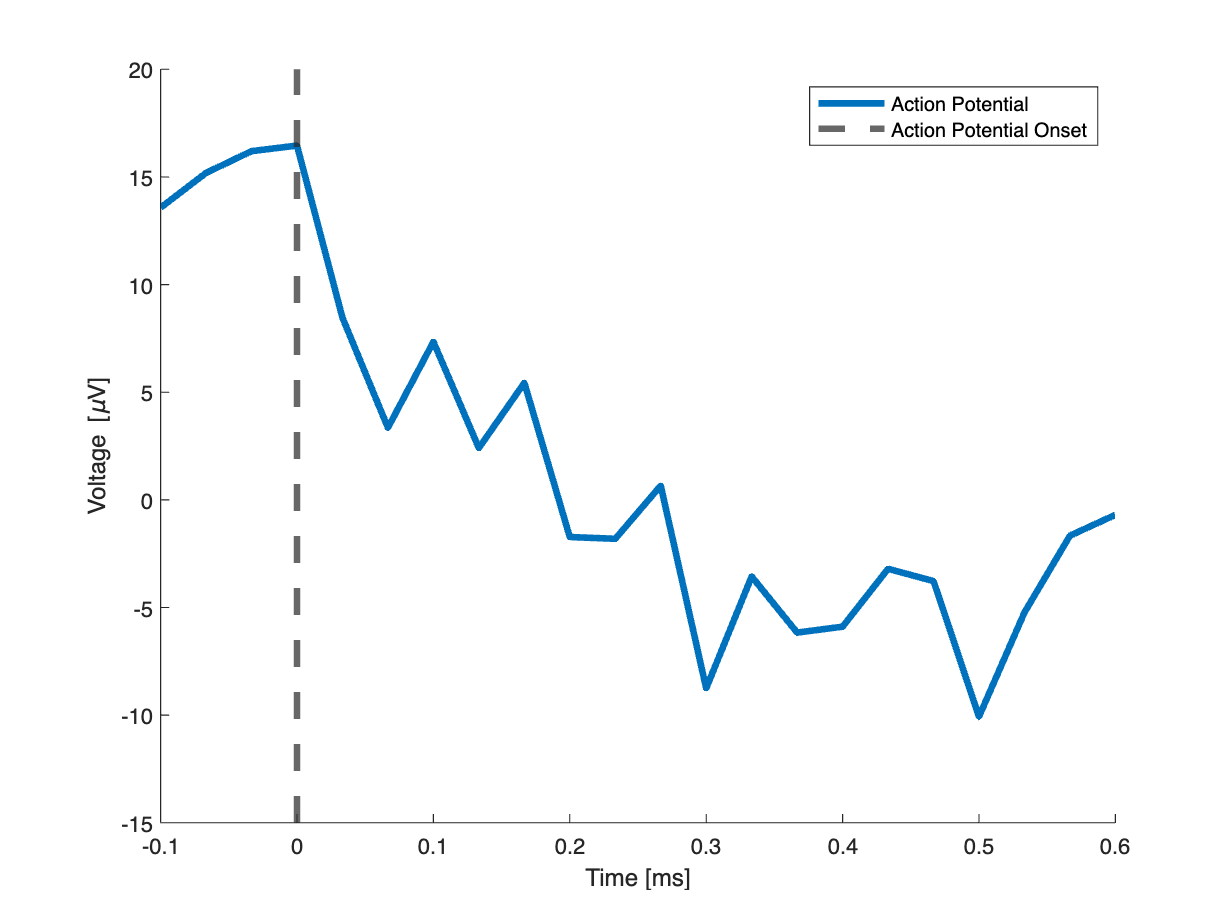

figure
waveform_time = (-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(0, LineWidth=3, LineStyle="--")
xlabel("Time [ms]")
ylabel("Voltage [\muV]")
legend(["Action Potential", "Action Potential Onset"])
box off

Now, consider the image below, which shows action potentials as a function of distance to a neuron. Which action potential has the best SNR in the image below? Which channel of data provides the best SNR? Where might each channel be in relation to a given neuron? Are any channels recording from multiple neurons? 

One of your requirements for this research project is to determine if there are any statistical differences in the SNR among the electrodes.

For more context about the image below, read the document titled *"Introduction to Neural Recordings"* under the Neural Recordings Reading Assignment on Canvas. 

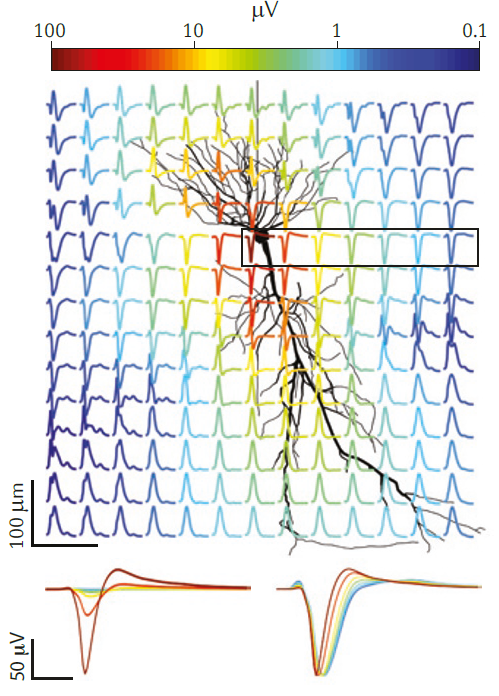

Calculate the SNR of each waveform in `spike_waveforms`. Use the following code to access each waveform:

% Initialize arrays to store SNR for each channel and waveform
snr_values = zeros(6, length(spike_waveforms{1}));

for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};
        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%
        % Define the spike and noise regions
        noise_region = waveform_data(end-11:end);  % Last 12 samples
        spike_region = waveform_data(1:10);  % First 10 samples
        
        % Calculate the mean amplitude of the spike (signal)
        spike_amplitude = max(spike_region);
        
        % Calculate the standard deviation of the noise
        noise_std = std(noise_region);
        
        % Calculate SNR for this waveform
        snr_values(chan_idx, waveform_idx) = spike_amplitude / noise_std;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end

After you've calculated SNRs, make sure to **plot the SNR values** and **run stats**!

% Display average SNR for each channel
avg_snr_per_channel = mean(snr_values, 2);
disp('Average SNR for each channel:');

Average SNR for each channel:


disp(avg_snr_per_channel);

    4.8302
    4.1024
    1.0298
    0.8842
    1.6230
    3.3259



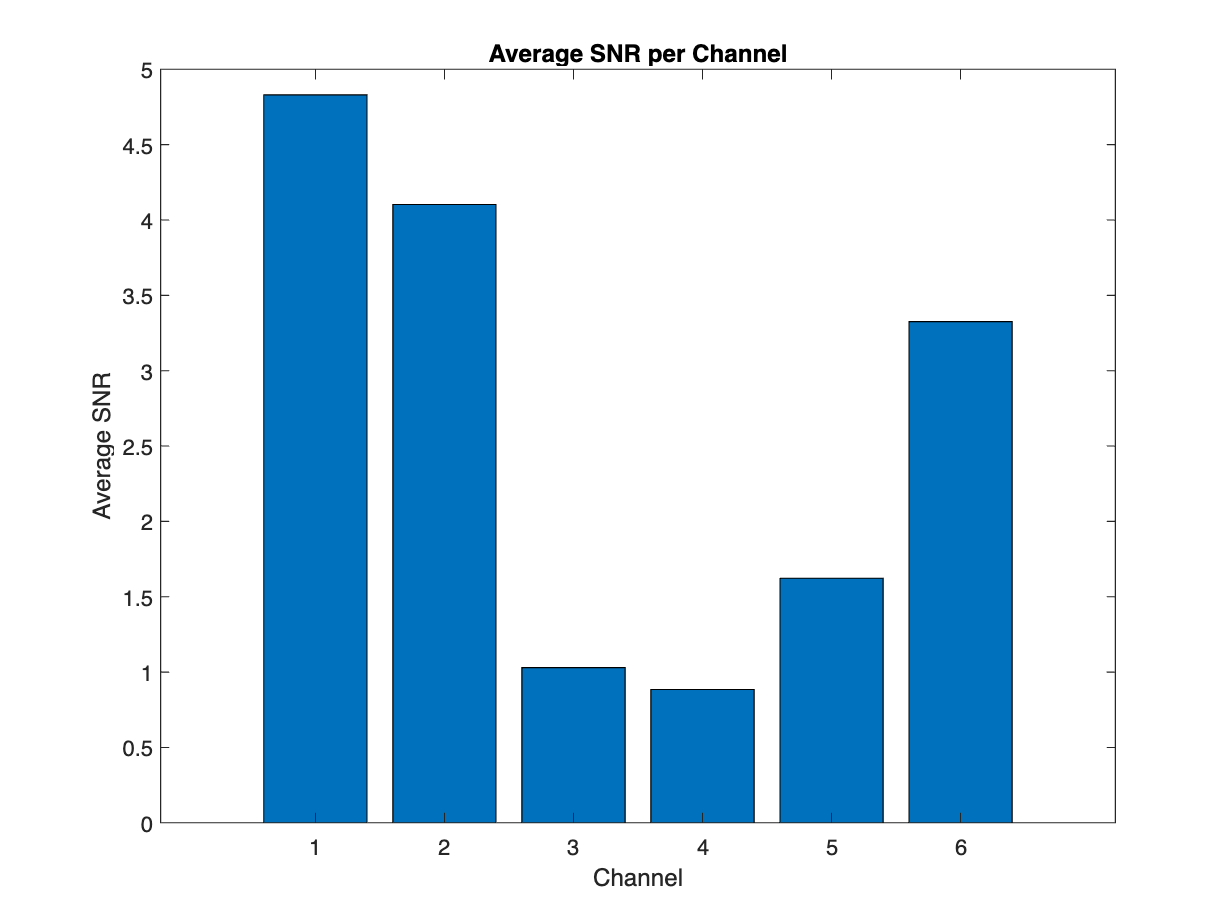

% Plot average SNR per channel
figure;
bar(avg_snr_per_channel);
title('Average SNR per Channel');
xlabel('Channel');
ylabel('Average SNR');

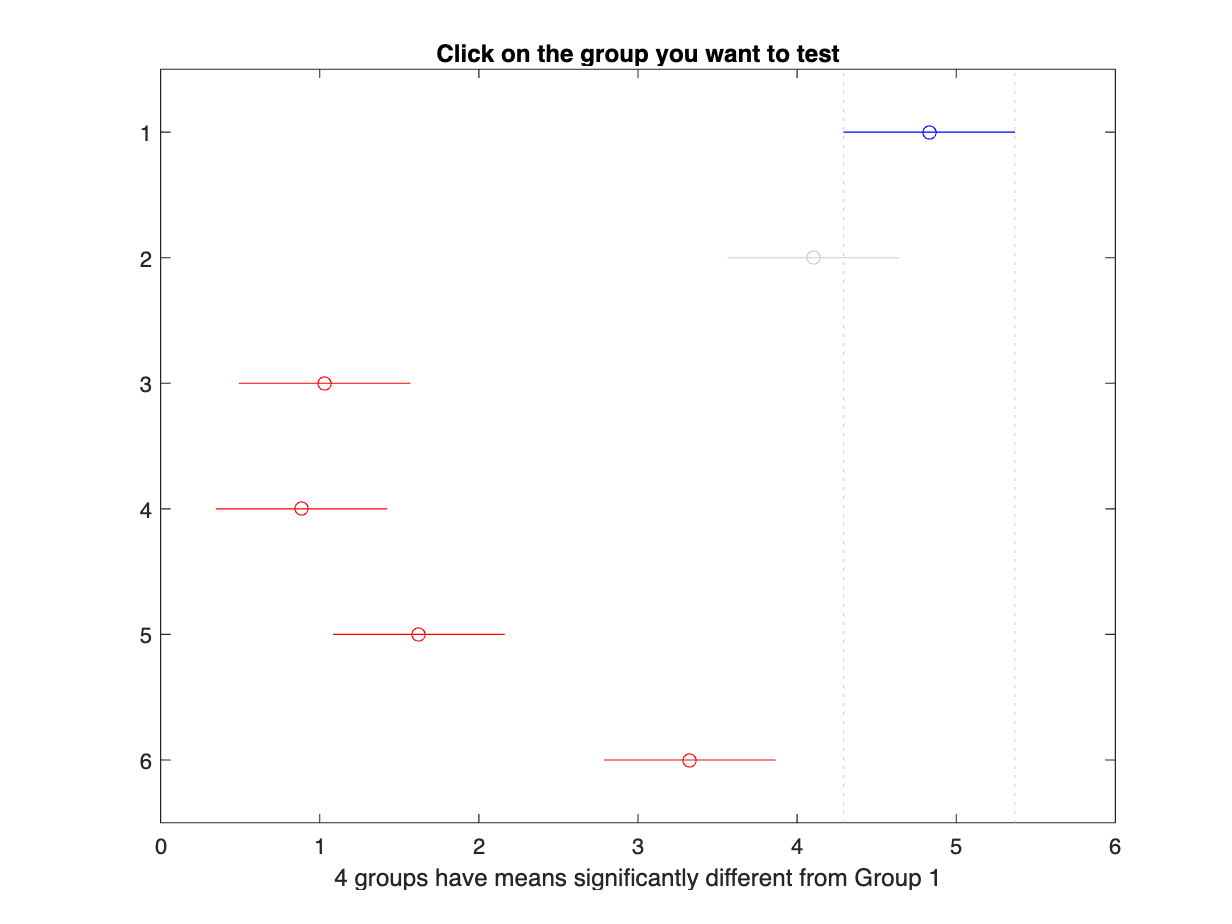

% Set significance level
alpha = 0.05;
snr_values_transposed = snr_values';
% Perform ANOVA for all channels
[~, ~, stats_anova] = anova1(snr_values_transposed, [], 'off');

% Perform multiple comparisons using Tukey's HSD test
[comparison_results, means, ~, ~] = multcompare(stats_anova, 'CType', 'hsd');

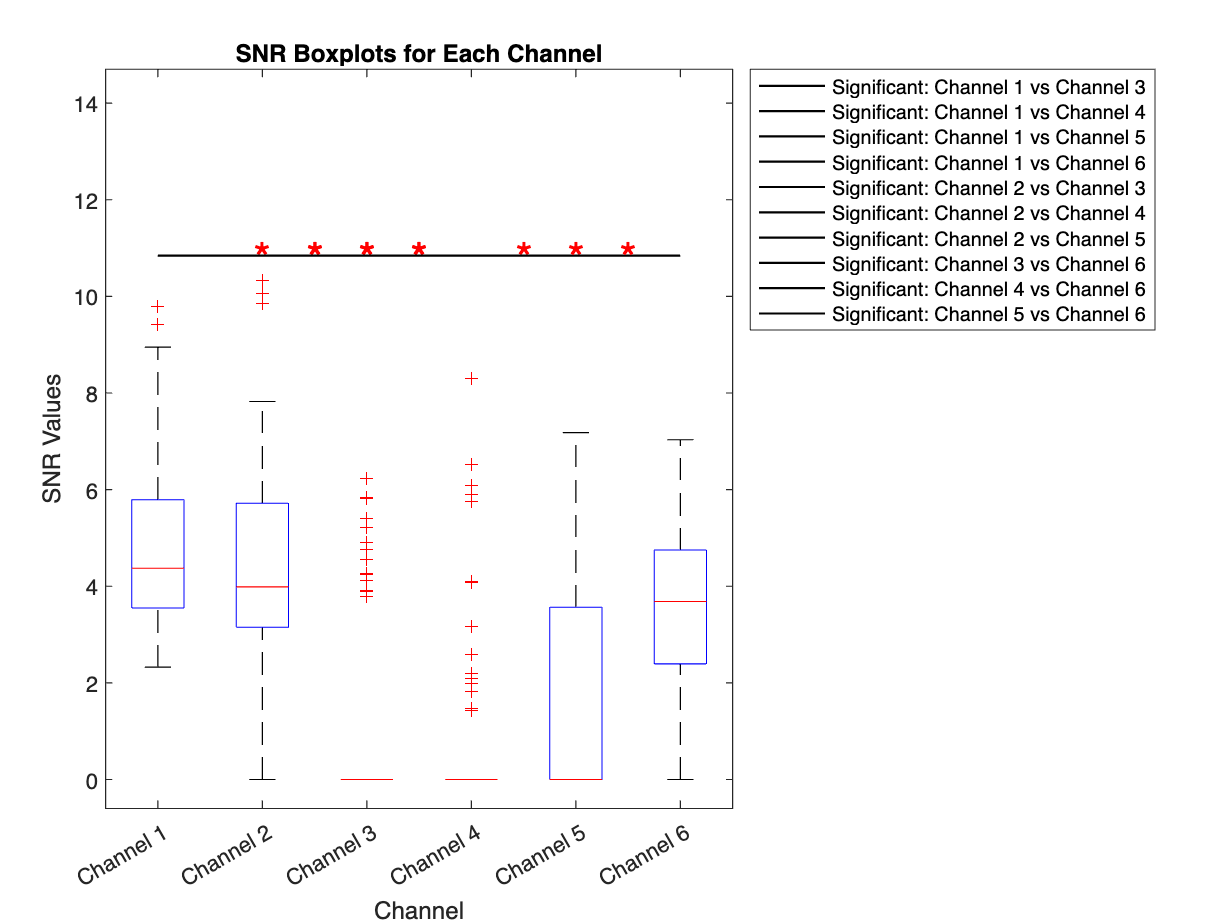

% Plot boxplots for each channel
figure;
h = boxplot(snr_values_transposed);
title('SNR Boxplots for Each Channel');
xlabel('Channel');
ylabel('SNR Values');
xticklabels({'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4', 'Channel 5', 'Channel 6'});

% Store channels with significant differences and the comparisons
significant_channels = [];
significant_comparisons = {};
for i = 1:size(comparison_results, 1)
    p_value = comparison_results(i, 6);
    if p_value < alpha
        channel1 = comparison_results(i, 1);
        channel2 = comparison_results(i, 2);
        significant_channels = [significant_channels; channel1, channel2];
        significant_comparisons{end+1} = sprintf('Channel %d vs Channel %d', channel1, channel2);
    end
end

% Annotate the plot to indicate significant differences
hold on;
for i = 1:size(significant_channels, 1)
    channel1 = significant_channels(i, 1);
    channel2 = significant_channels(i, 2);
    y_value = max(max(snr_values_transposed(:))) * 1.05;  % Adjust the height of the brackets
    plot([channel1, channel2], [y_value, y_value], 'black-', 'LineWidth', 1);  % Use red for significant differences
    text(mean([channel1, channel2]), y_value, '*', 'Color', 'r', 'FontSize', 20, 'HorizontalAlignment', 'center');  % Use red for asterisks
end
hold off;

% Create a legend
legend(h(1:6), 'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4', 'Channel 5', 'Channel 6');

% Display the significant comparisons in the legend
for i = 1:numel(significant_comparisons)
    legendInfo{i} = ['Significant: ', significant_comparisons{i}];
end
lgd = legend(legendInfo);
set(lgd, 'Location', 'BestOutside');  % Adjust legend location
ylim([-0.60 14.7])

## Feature Extraction

The only requirement for generating features is that the length of your `neural_features` must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information about this requirement, check notebook 03 on training the neural network.

If the lengths don't match as a result of your calculations, you can [pad the array with zeros](https://www.mathworks.com/help/images/ref/padarray.html).

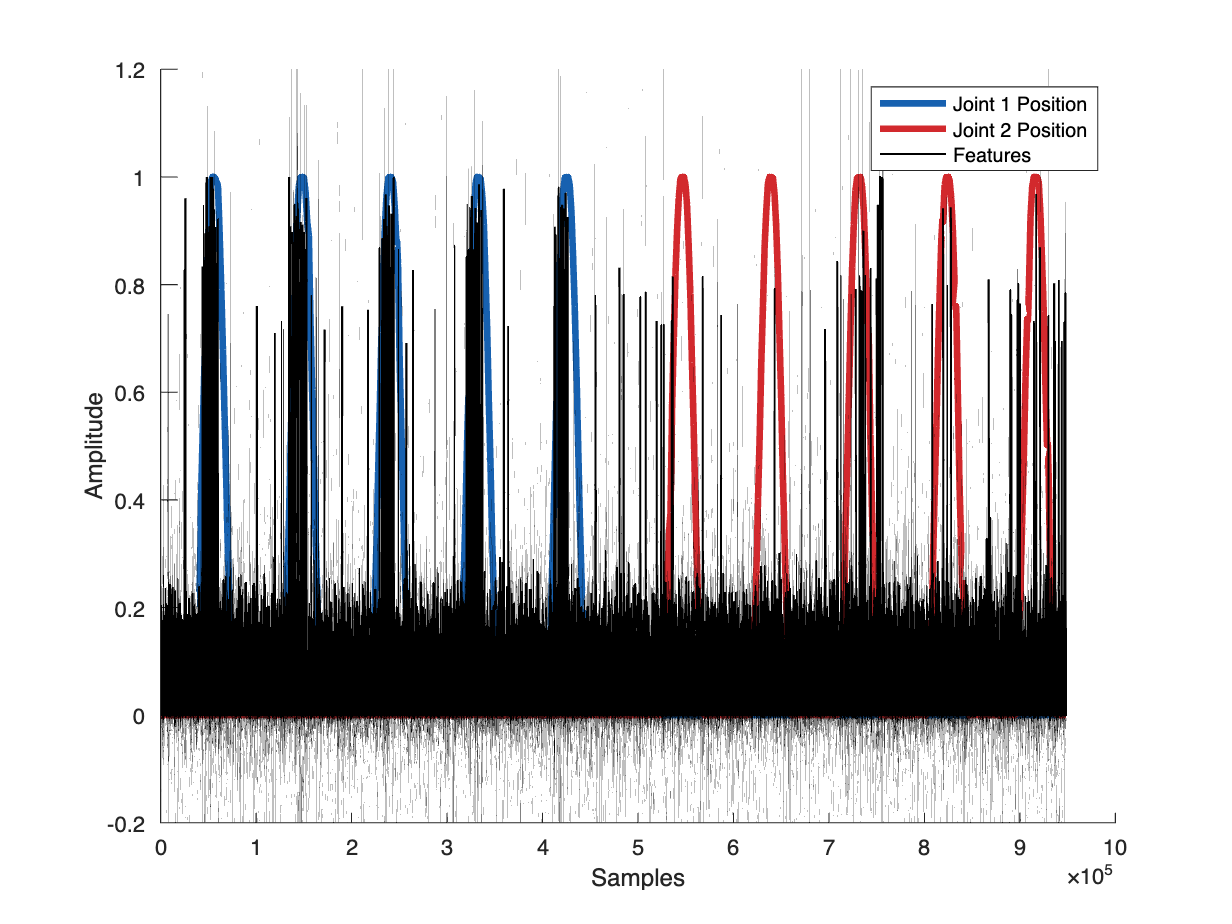

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% % 2. Interpolation for Smoothing
% % Interpolate the raw neural data using linear interpolation
% smoothed_neural_data = interp1(1:size(filt_neural_data, 1), filt_neural_data, 'linear');
% 
% %Set the weight for spike locations (higher weight to retain spikes)
% spike_weight = 5;  % Adjust as needed based on the desired weight
% 
% % Initialize the neural features array
% neural_features = zeros(size(filt_neural_data));
% 
% % Apply weighted moving average to each channel separately
% for channel = 1:size(filt_neural_data, 2)
%     % Apply weighted moving average with higher weight for spike locations
%     neural_features(:, channel) = filt_neural_data(:, channel) .* (1 - spike_locations(:, channel)) + ...
%                                   spike_locations(:, channel) * spike_weight;
% 
%     % Normalize to ensure the weights sum to 1
%     neural_features(:, channel) = neural_features(:, channel) / sum(neural_features(:, channel));
% end

%%%%%%%%%%%%%%%%%%%%%%% FIRST ATTEMPT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Set parameters for the custom filter
% spike_weight = 5;  % Weight for spike locations
% filter_length = 500;  % Filter length, adjust as needed based on the desired smoothing
% 
% % Design a custom filter with higher weights for spike locations
% custom_filter = ones(1, filter_length);
% custom_filter(floor(filter_length/2) + 1) = spike_weight;  % Place higher weight at the center
% 
% % Initialize the neural features array
% smoothed_neural_data = zeros(size(filt_neural_data));
% 
% % Apply the custom filter to each channel separately
% for channel = 1:size(filt_neural_data, 2)
%     % Apply the custom filter with spike locations emphasized
%     smoothed_channel = conv(filt_neural_data(:, channel), custom_filter, 'same');
% 
%     % Make negative values at spike locations positive
%     %smoothed_channel(spike_locations(:, channel)) = abs(smoothed_channel(spike_locations(:, channel)));
% 
%     % Assign the smoothed channel to the neural features
%     smoothed_neural_data(:, channel) = smoothed_channel;
% end
%%%%%%%%%%%%%%%%%%%%%%% FIRST ATTEMPT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% % Parameters for peak detection
% threshold = 0.1;  % Adjust as needed based on the signal characteristics
% min_peak_distance = 100;  % Minimum distance between peaks, adjust as needed
% 
% % Initialize the spike locations array
% spike_locations = zeros(size(smoothed_neural_data));
% 
% % Detect peaks in each channel and mark the spike locations
% for channel = 1:size(smoothed_neural_data, 2)
%     [peaks, peak_locs] = findpeaks(smoothed_neural_data(:, channel), ...
%         'MinPeakHeight', threshold, 'MinPeakDistance', min_peak_distance);
% 
%     % Mark the spike locations
%     spike_locations(peak_locs, channel) = 1;
% end
% 
% % Check the size of the resulting spike locations
% spike_size = size(spike_locations);
% 
% % Parameters for feature extraction
% window_before = 10;  % Number of samples before the peak
% window_after = 10;   % Number of samples after the peak
% 
% % Initialize the neural features array
% neural_features = smoothed_neural_data;
% 
% % Extract features for each channel
% for channel = 1:size(smoothed_neural_data, 2)
%     % Get the indices of the detected peaks for the current channel
%     peak_indices = find(spike_locations(:, channel));
% 
%     % Loop through each detected peak
%     for i = 1:length(peak_indices)
%         % Get the window of data around the peak
%         start_index = max(1, peak_indices(i) - window_before);
%         end_index = min(size(smoothed_neural_data, 1), peak_indices(i) + window_after);
%         feature_window = smoothed_neural_data(start_index:end_index, channel);
% 
%         % Replace the corresponding locations in neural_features with the feature window
%         neural_features(start_index:end_index, channel) = feature_window;
%     end
% end


%%%%%%%%%%%%%%%%%%%%%%%%%%% BETTER APPROACH %%%%%%%%%%%%%%%%%%%%%%%%
%Sampling rate and standard deviation for a 100ms window
sampling_rate = 30000;  % Change to your actual sampling rate
window_std = (100 / 1000) * sampling_rate;

% Generate the Gaussian window
window_length = 2 * ceil(4 * window_std) + 1;
gaussian_window = gausswin(window_length, window_std);

% Normalize the Gaussian window to have unit area
gaussian_window = gaussian_window / sum(gaussian_window);

% Initialize the smoothed data array
smoothed_data = zeros(size(filt_neural_data));

% Smooth each channel with the Gaussian window
for channel = 1:size(filt_neural_data, 2)
    % Convolve the data with the Gaussian window
    smoothed_channel = conv(filt_neural_data(:, channel), gaussian_window, 'same');

    % Emphasize spike locations by adding original spike locations (scaled) to the smoothed data
    scaling_factor = max(smoothed_channel) * 2;  % Adjust this scaling factor as needed
    smoothed_data(:, channel) = smoothed_channel + scaling_factor * spike_locations(:, channel);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%% BETTER APPROACH %%%%%%%%%%%%%%%%%%%%%%%%
neural_features2 = abs(smoothed_data);
% neural_features(~spike_locations) = 0;
% neural_features = normalize(neural_features, "range", [0, 1]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features2) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

figure
hold on
plot(training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(normalize(neural_features2, "range", [0 1]),'Color',"#000000" ,'LineWidth', 1)
hold off
box off
xlabel("Samples")
ylabel("Amplitude")
legend(["Joint 1 Position", "Joint 2 Position", "Features"])

save("results\features_attempt_2", "neural_features2")

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.DisplayLabels = ["Hand Kinematics 1", "Hand Kinematics 2", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan) ' spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end